file = "data\perf_gcs_rand_corridor2.csv";
data = importdata(file, ',', 1);
tottime = data.data(:, 4);
bordersize = data.data(:, 5);

en = true;
h = figure('Position',[0,0,1200,500]);

% Curve fit
% subplot('Position',[0.5 0 0.5 0.9]);
subp = subplot(1,3,[2:3]);
hold on;
axis([0, 150, 0 ,4]);
xticks(0:20:160);
yticks(0:1:4);
grid('minor');
% yline(1, "Color", [0.9, 0.2, 0]);
% plot([0,80, 80], [1, 1, 0], '--',"Color", [0.9, 0.2, 0])
area([0,100, 100], [2, 2, 0], "LineStyle","none", "FaceColor",[1, 0.7, 0.1], "FaceAlpha", .1);
area([0,80, 80], [1, 1, 0], "LineStyle","none", "FaceColor",[1, 0.6, 0.1], "FaceAlpha", .2);
plot(bordersize, tottime,".", "Color", [0.5,0.5,0.5], "MarkerSize", 8);

[fitresult, gof] = fit_bordersize_searchtime2(bordersize, tottime)

fitresult =      常规模型:
     fitresult(x) = a*exp(b*x)
     系数(置信边界为 95%):
       a =     0.07935  (0.0698, 0.0889)
       b =     0.02612  (0.02495, 0.02728)

gof = 包含以下字段的 struct :
           sse: 126.7994
       rsquare: 0.5650
           dfe: 998
    adjrsquare: 0.5646
          rmse: 0.3564


if en
    legend( '', '', 'Time - Border Length', 'Exponential fit', 'Lower bound', 'Upper bound', 'Location', 'NorthWest', 'Interpreter', 'none' );
    % 为坐标区加标签
    xlabel( 'Border Length(unit)', 'Interpreter', 'none' );
    % ylabel( 'Time(ms)', 'Interpreter', 'none' );
else
    legend( '', '',  '搜索时间-交线边界长度', '指数拟合曲线', '下界(指数拟合曲线)', '上界(指数拟合曲线)', 'Location', 'NorthWest', 'Interpreter', 'none' );
    % 为坐标区加标签
    xlabel( '边界交线长度(unit)', 'Interpreter', 'none' );
    % ylabel( '搜索时间(ms)', 'Interpreter', 'none' );
end

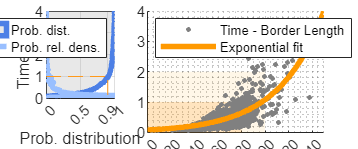

hold off;
% probability distribution

Y = tottime;
time_range = [0, 4];
resolution = 100;
time_res = linspace(time_range(1), time_range(2), resolution+1);
cnt = zeros(1, resolution+1);
cnt_accum = zeros(1, resolution+1);
for i = 1:length(Y)
    for j = 1:resolution
        if Y(i) >= time_res(j) && Y(i) < time_res(j+1)
            cnt(j) = cnt(j) + 1;
            break;
        end
    end
end
for i = 1:resolution
    cnt_accum(i+1) = cnt_accum(i) + cnt(i);
end

subp = subplot(1,3,[1]);
hold on;
axis([0, 1, 0 ,4]);
yticks(0:1:4);
xticks([0 0.5 0.9 1]);
% xticklabels( cellfun(@(x) [num2str(x*100), '%'], num2cell(subp.XTick), 'UniformOutput', false))
% text(0.9, 0.0, '0.9', 'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
grid('on');
ylabel( 'Time(ms)', 'Interpreter', 'none' );
xlabel( 'Prob. distribution', 'Interpreter', 'none' );

line_wid = 3;
area(cnt_accum/length(tottime),time_res, "LineWidth", line_wid, ...
    "FaceColor", [0.7, 0.7, 0.7], "FaceAlpha", 0.3, ...
    "EdgeColor", [0.3, 0.5, 0.9]);
area(cnt_accum/length(tottime),time_range(2), "LineWidth", 1, ...
    "FaceColor", [1, 0.7, 0.1], "FaceAlpha", 0.3, ...
    "EdgeColor", [1, 0.7, 0.1]);
plot(cnt/max(cnt),time_res, "LineWidth", line_wid, "Color", [0.6, 0.75, 1.0]);

% yline(1, "Color", [0.9, 0.2, 0]);
plot([0,0.9, 0.9], [1, 1, 0], '--',"Color", [1, 0.6, 0.1])
legend(  'Prob. dist.', '', 'Prob. rel. dens.', 'Location', 'North');
hold off;